# K-NN

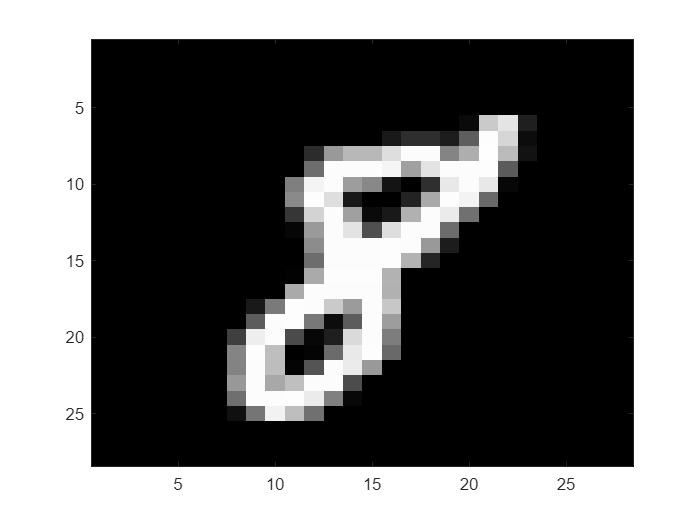

clear;clc;
load('mnist.mat');
colormap(gray);
image(training.images(:,:,18)*255);

training.labels(18)

ans = 8

## Data Preparation

X_train = zeros(training.count, training.height*training.width);
for i=1:training.count
    X_train(i,:) = reshape(training.images(:,:,i),[1,training.height*training.width]);
end
X_test = zeros(test.count, test.height*test.width);
for i=1:test.count
    X_test(i,:) = reshape(test.images(:,:,i),[1,test.height*test.width]);
end

n_test = 100;
n_dim = 50;
coeff = pca(X_train);
reduced_coeff = coeff(:,1:n_dim);
X_train = X_train*reduced_coeff;
X_test = X_test*reduced_coeff;

idx = randperm(size(X_test,1));
% idx = 1:size(X_test,1);
idx = idx(1:n_test);
X_test = X_test(idx,:);

C = 10;
Y_train = training.labels+1;
Y_test = test.labels+1;
Y_test = Y_test(idx,:);

dists = zeros(size(X_test,1),size(X_train,1));
for i=1:size(X_test,1)
    for j=1:size(X_train,1)
        dists(i,j) = norm(X_train(j,:)-X_test(i,:));
    end
end

## Inference

params = [1, 3, 5, 10, 20, 30, 40, 50, 60];
stats = zeros(size(params,2),1);
for n=1:size(params,2)
    K=params(n);
    Y_pred = [];
    for i = 1:size(X_test,1)
        dist = dists(i,:);
        offset = max(dist)+1;
        votes = zeros(C,1);
        for k=1:K
            [~, c] = min(dist);
            votes(Y_train(c)) = votes(Y_train(c)) + 1;
            dist(c) = offset;
        end
        [~, c] = max(votes);
        Y_pred = [Y_pred; c];
    end
    acc = sum(Y_pred==Y_test)/size(Y_test,1);
    disp(['K:' num2str(K) ' | Accuracy:' num2str(acc)]);
    stats(n) = acc;
end

K:1 | Accuracy:0.98
K:3 | Accuracy:0.98
K:5 | Accuracy:0.99
K:10 | Accuracy:0.99
K:20 | Accuracy:0.98
K:30 | Accuracy:0.98
K:40 | Accuracy:0.96
K:50 | Accuracy:0.97
K:60 | Accuracy:0.96


## Plot

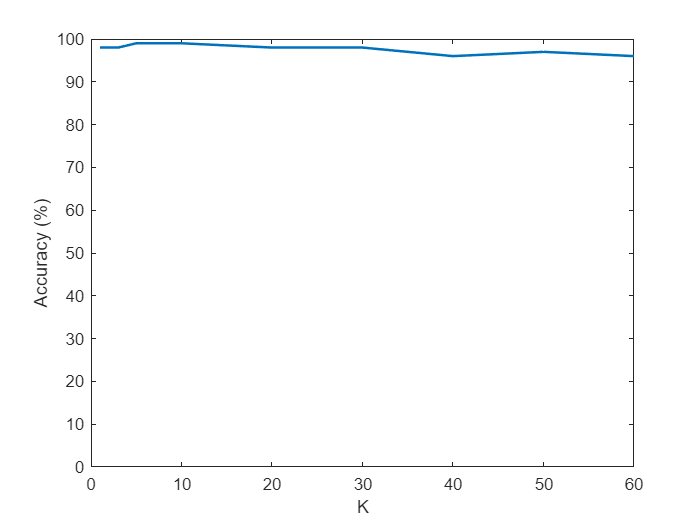

plot(params,stats*100, 'LineWidth', 1.5);
axis([0 max(params) 0 100]);
xlabel('K');
ylabel('Accuracy (%)');